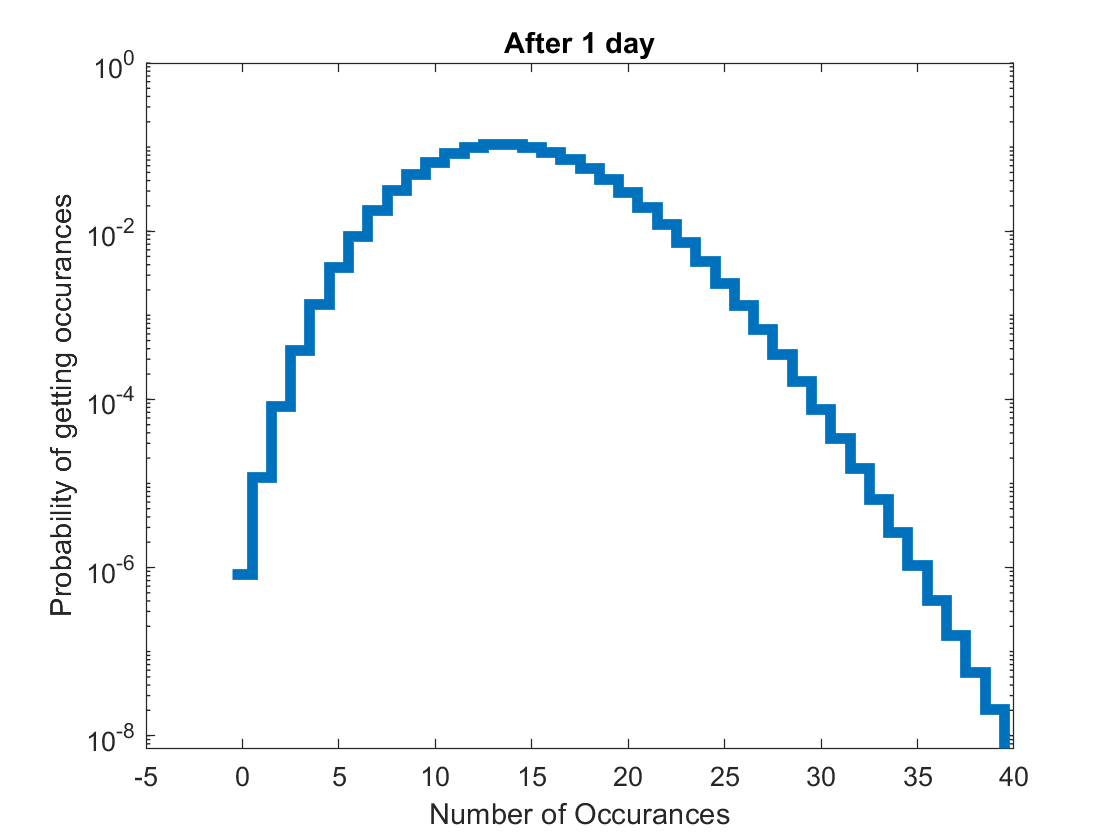

gitclear, close all, clc

X = 14;
Y = 20;
x = 0:40;
poisson = makedist("Poisson", 'lambda',X);
stairs(x-0.5,pdf(poisson,x),"LineWidth",4);
set(gca,'YScale','log')
title("After 1 day")
xlabel("Number of Occurances")
ylabel("Probability of getting occurances")

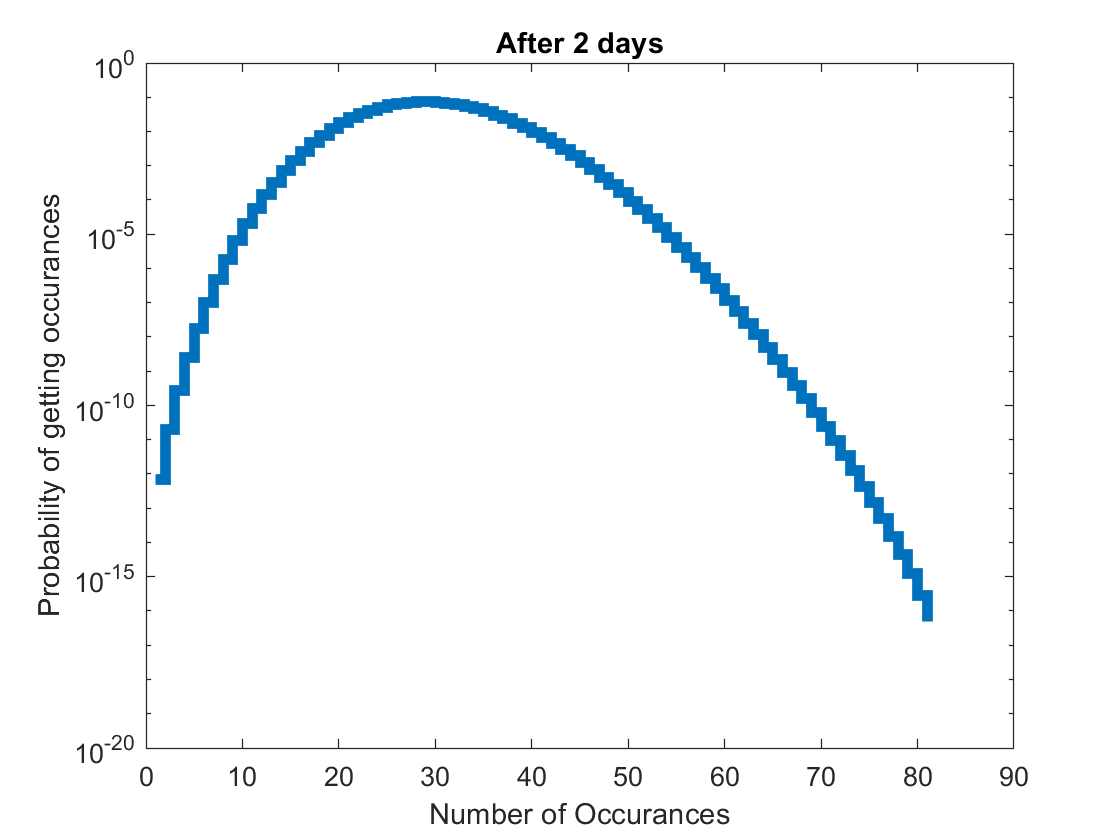

days_1 = pdf(poisson,x);

days_2 = conv(pdf(poisson,x),pdf(poisson,x));
ave_2 = conv(pdf(poisson,x/2),pdf(poisson,x/2));
ave_3 = conv(conv(pdf(poisson,x/3),pdf(poisson,x/3)),pdf(poisson,x/3));
ave_4 = conv(conv(conv(pdf(poisson,x/4),pdf(poisson,x/4)),pdf(poisson,x/4)),pdf(poisson,x/4));
ave_5 = conv(conv(conv(conv(pdf(poisson,x/5),pdf(poisson,x/5)),pdf(poisson,x/5)),pdf(poisson,x/5)),pdf(poisson,x/5));

stairs(days_2,"LineWidth",4);
set(gca,'YScale','log')
title("After 2 days")
xlabel("Number of Occurances")
ylabel("Probability of getting occurances")

As I integrate over 2 days the probability of the background decreased overall.

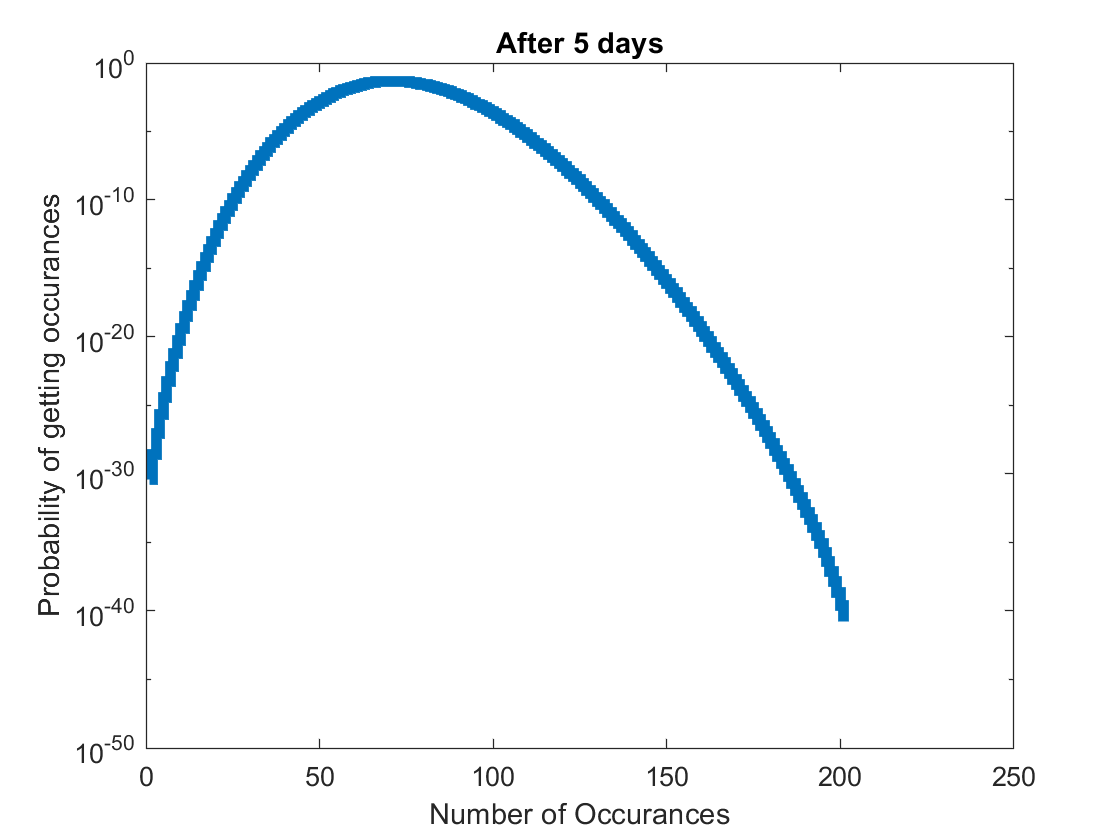

days_3 = conv(days_2,pdf(poisson,x));
days_4 = conv(days_3,pdf(poisson,x));
days_5 = conv(days_4, pdf(poisson,x));

stairs(days_5,"LineWidth",4);
set(gca,'YScale','log')
title("After 5 days")
xlabel("Number of Occurances")
ylabel("Probability of getting occurances")

After 5 days, the distribution is still poisson. This makes sense since we are still measuring the same background distribution. Nothing about the situation has changed in the past 5 days. Mathematically it makes sense because we are just convolving or taking the sum of the probabilities of two PDF's of poisson distributions. 

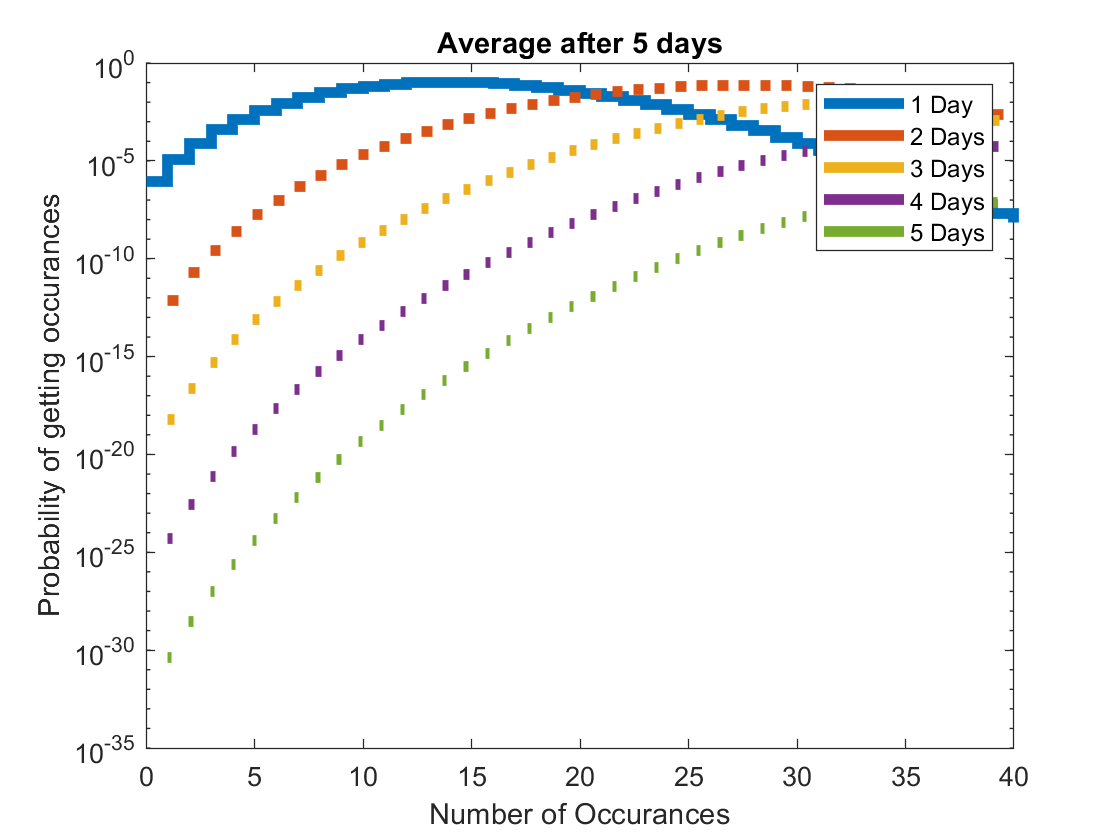

stairs(x,days_1,"LineWidth",4);
hold on
stairs(linspace(1,40,81),ave_2,"LineWidth",4);
stairs(linspace(1,40,121),ave_3,"LineWidth",4);
stairs(linspace(1,40,161),ave_4,"LineWidth",4);
stairs(linspace(1,40,201),ave_5,"LineWidth",4);
set(gca,'YScale','log')
title("Average after 5 days")
legend("1 Day", "2 Days", "3 Days", "4 Days", "5 Days")
xlabel("Number of Occurances")
ylabel("Probability of getting occurances")

mean_conv(1) = 14;
mean_conv(2) = sum(ave_2.*linspace(1,40,81))/sum(ave_2, 'all');
mean_conv(3) = sum(ave_3.*linspace(1,40,121))/sum(ave_3, 'all');
mean_conv(4) = sum(ave_4.*linspace(1,40,161))/sum(ave_4, 'all');
mean_conv(5) = sum(ave_5.*linspace(1,40,201))/sum(ave_5, 'all');

hold off

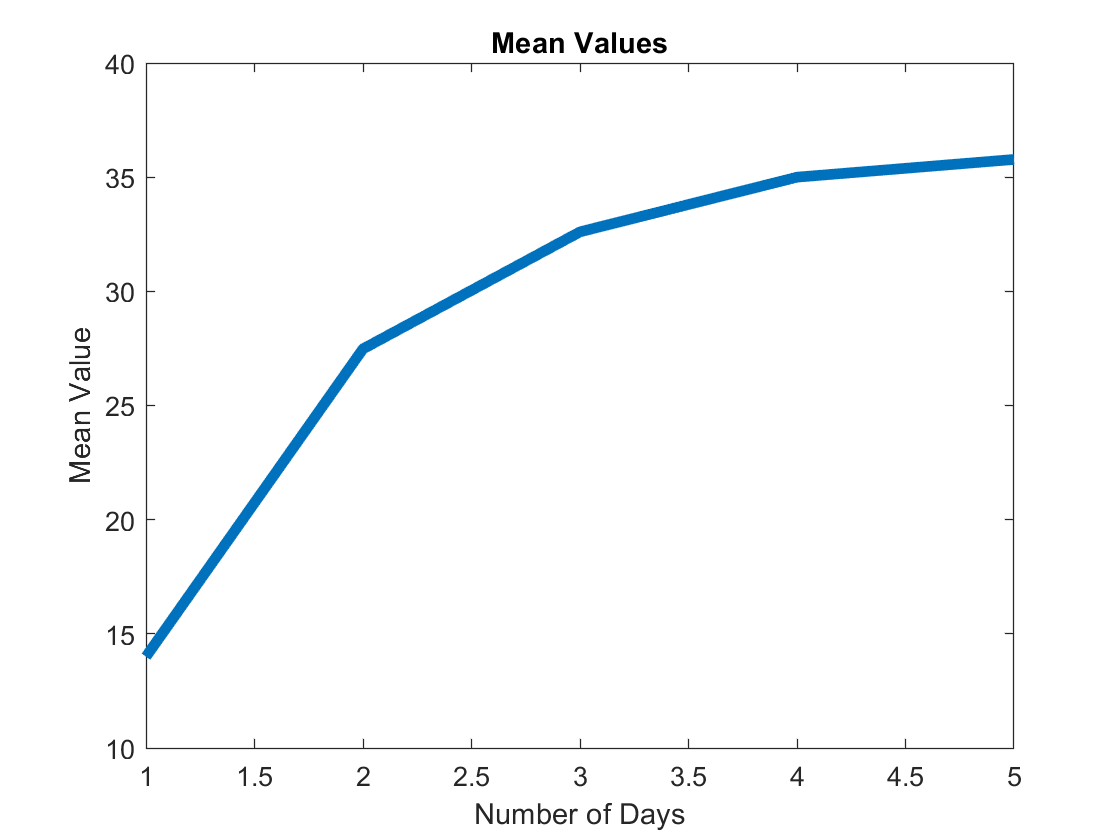

plot(mean_conv,"LineWidth",4)
title("Mean Values")
ylabel("Mean Value")
xlabel("Number of Days")

The average over an increasing range of days becomes more gaussian like due to the central limit theorem. The mean also increases and converges to a mean value. This is shown by calculating the weighted mean of each average distribution and then seeing that the difference between the average is decreasing. This is also shown in the "Mean Values" plot to the right.

We chose 3 days, since we chose Y to be 20, that means we are looking for the sigma of 60 gamma rays.

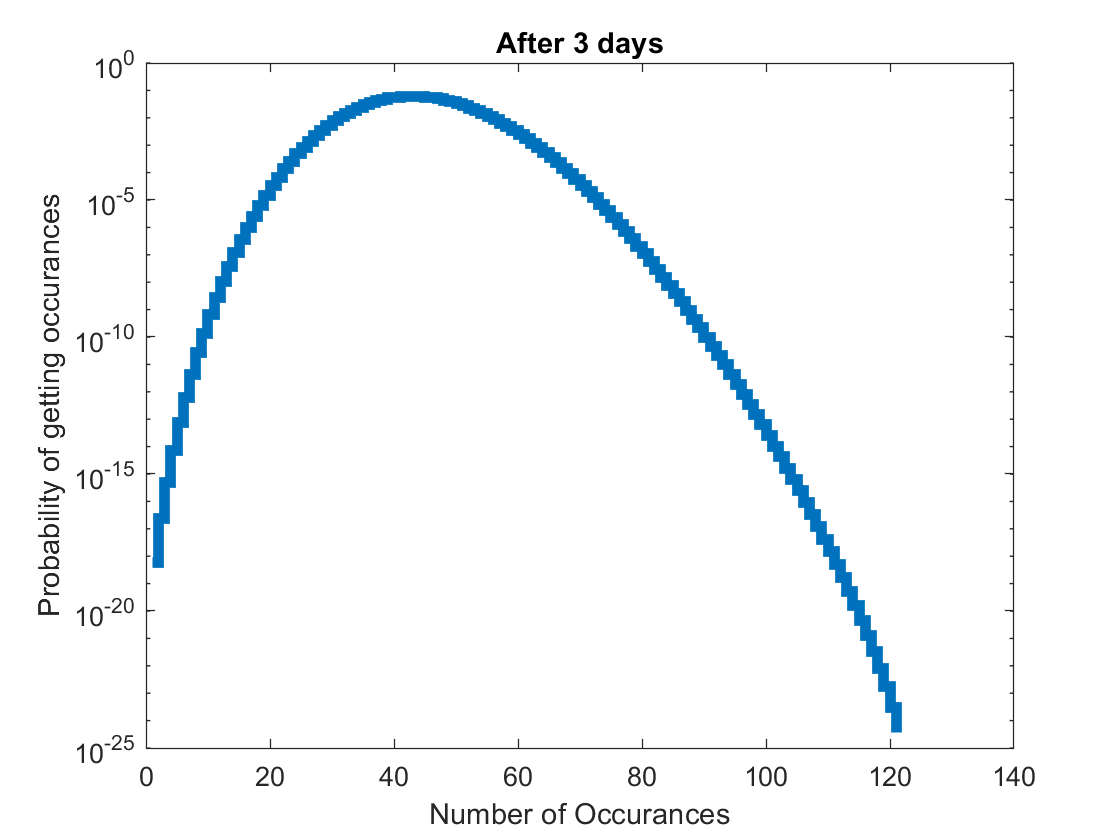

N = 3;
gams = Y*N;

stairs(days_3,"LineWidth",4);
set(gca,'YScale','log')
title("After 3 days")
xlabel("Number of Occurances")
ylabel("Probability of getting occurances")

i = 0;
for k = 1:length(days_3)-gams
    i = i + 1;
    sum_days3(i) = days_3(k+gams);
end
Sum_days3 = sum(sum_days3);
sig_vals = abs(icdf('Normal', Sum_days3,0,1))

sig_vals =    2.563631936235080


The sigma of my observation is 2.5636. 

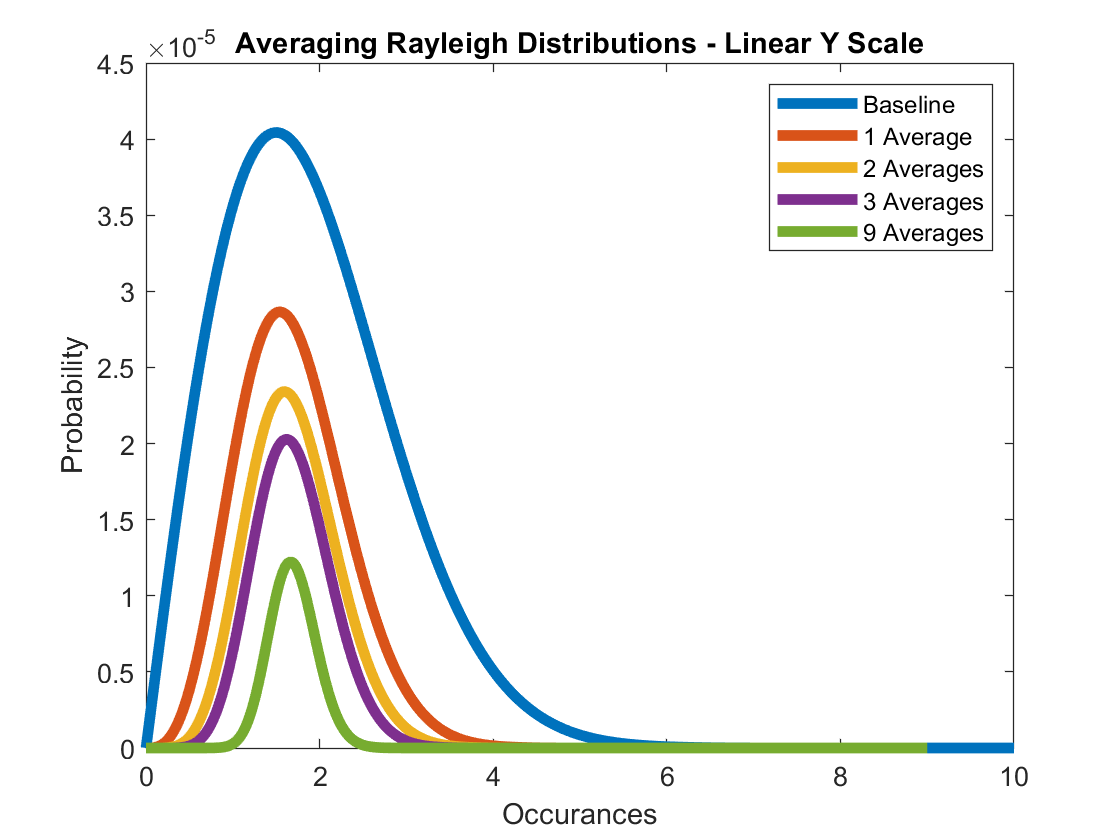

x = linspace(0,10,100000);
sig = 1.5;
rayl = makedist("Rayleigh",sig);
plot(x,pdf(rayl,x)/sum(pdf(rayl,x)),"LineWidth",4);
hold on

dist2 = conv(pdf(rayl,x),pdf(rayl,x));
dist3 = conv(conv(pdf(rayl,x),pdf(rayl,x)),pdf(rayl,x));
dist4 = conv(conv(conv(pdf(rayl,x),pdf(rayl,x)),pdf(rayl,x)),pdf(rayl,x));
vec2 = pdf(rayl,x);
 for k = 1:10
     vec1 = myAverage(pdf(rayl,x), vec2);
     vec2 = vec1;
 end
dist10 = vec2;
dist2_length = linspace(1,10,length(dist2));
dist3_length = linspace(1,10,length(dist3));
dist4_length = linspace(1,10,length(dist4));
dist10_length = linspace(1,10,length(dist10));
plot(dist2_length-1, dist2/(sum(dist2)),"LineWidth",4);
plot(dist3_length-1, dist3/(sum(dist3)),"LineWidth",4);
plot(dist4_length-1, dist4/(sum(dist4)),"LineWidth",4);
plot(dist10_length-1, dist10/(sum(dist10)),"LineWidth",4);
title('Averaging Rayleigh Distributions - Linear Y Scale')
xlabel('Occurances')
ylabel('Probability')
legend('Baseline', '1 Average', '2 Averages', '3 Averages', '9 Averages')
hold off

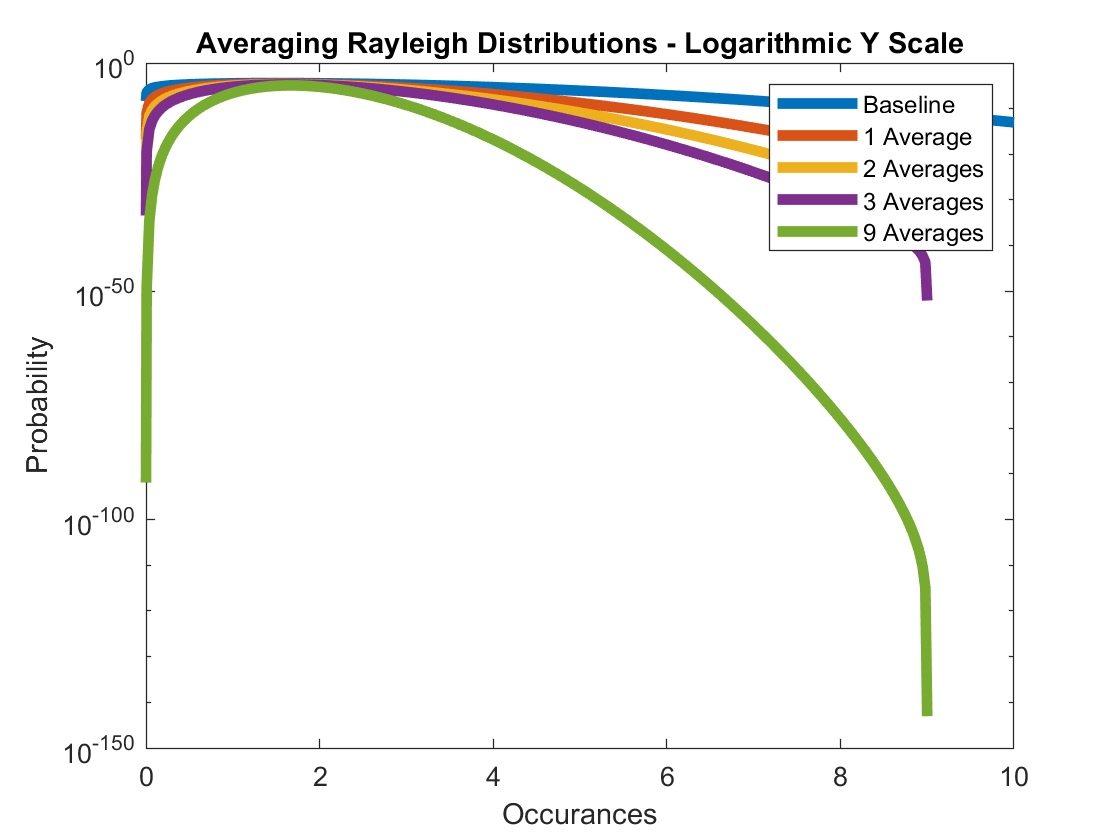


 
semilogy(x,pdf(rayl,x)/sum(pdf(rayl,x)),"LineWidth",4);
hold on
semilogy(dist2_length-1, dist2/(sum(dist2)),"LineWidth",4);
semilogy(dist3_length-1, dist3/(sum(dist3)),"LineWidth",4);
semilogy(dist4_length-1, dist4/(sum(dist4)),"LineWidth",4);
semilogy(dist10_length-1, dist10/(sum(dist10)),"LineWidth",4);
title('Averaging Rayleigh Distributions - Logarithmic Y Scale')
xlabel('Occurances')
ylabel('Probability')
legend('Baseline', '1 Average', '2 Averages', '3 Averages', '9 Averages')
hold off

As the shape changes it approaches the appearance of a gaussian distribution after roughly 2 intervals looking at the linear y-scale plot. Looking at the logarithmic y-scale plot it takes at least 9 averages to start to resemble a normal distribution.

Question 3

Version 1

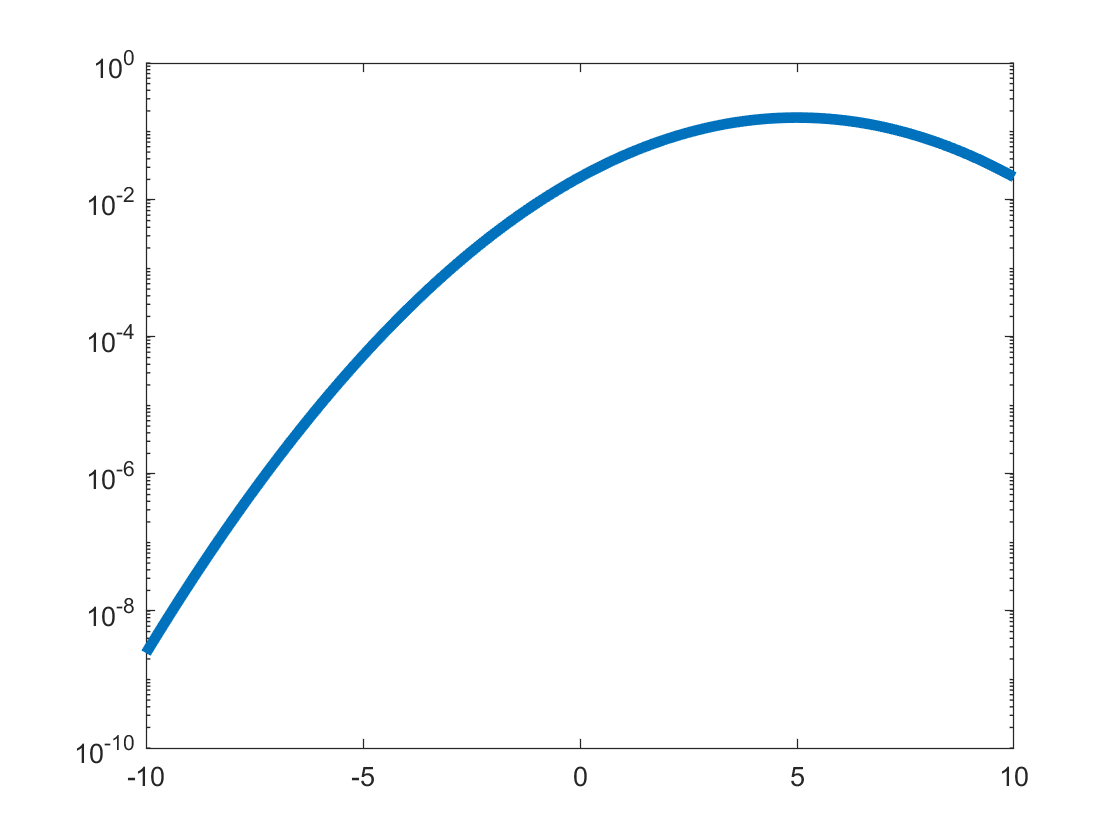

x_hyp = 7;
y = 5*pi;

x = linspace(-10,10,1000);
sig = 2.5;
mu = 5;
gaus = makedist("Normal",mu,sig);

prob = 1 - cdf(gaus,y);
sig_val = abs(icdf('Normal', prob, 0, 1));

I recieve a sigma value of 4.2832. Not quite the 5 sigma value we need.

Version 2:

prob_y = 10000*(1-cdf(gaus, y))

prob_y =    0.092118303380850


sig_valy = icdf(gaus,prob_y)

sig_valy =    1.680442650560924


After using a trials factor of 10k I get a sigma value of 1.6804. Significantly less then the 5 sigma minimum to be considered and observation.

Problem 4

prob5sig = 1/3.5e6;
det = icdf(gaus, 1-prob5sig)

det =   17.501578587325952


det_10k = icdf(gaus, 1-(prob5sig/10000))

det_10k =   21.377565985128967


The signal required using a trial factor of one is 17.5015. The signal required using a trial factor of 10k is 21.3776.

Probx = (1-cdf(gaus, det,0,1))

Probx =      2.857142856749206e-07


Probx_10k = (1-cdf(gaus, det_10k,0,1))*10000

Probx_10k =      2.857147851642594e-07


brghtness_factor = det_10k/det

brghtness_factor =    1.221465016910525


The signal using a trial factor of 10k must be roughly 1.22 times brighter then the signal using a trial factor of 1.

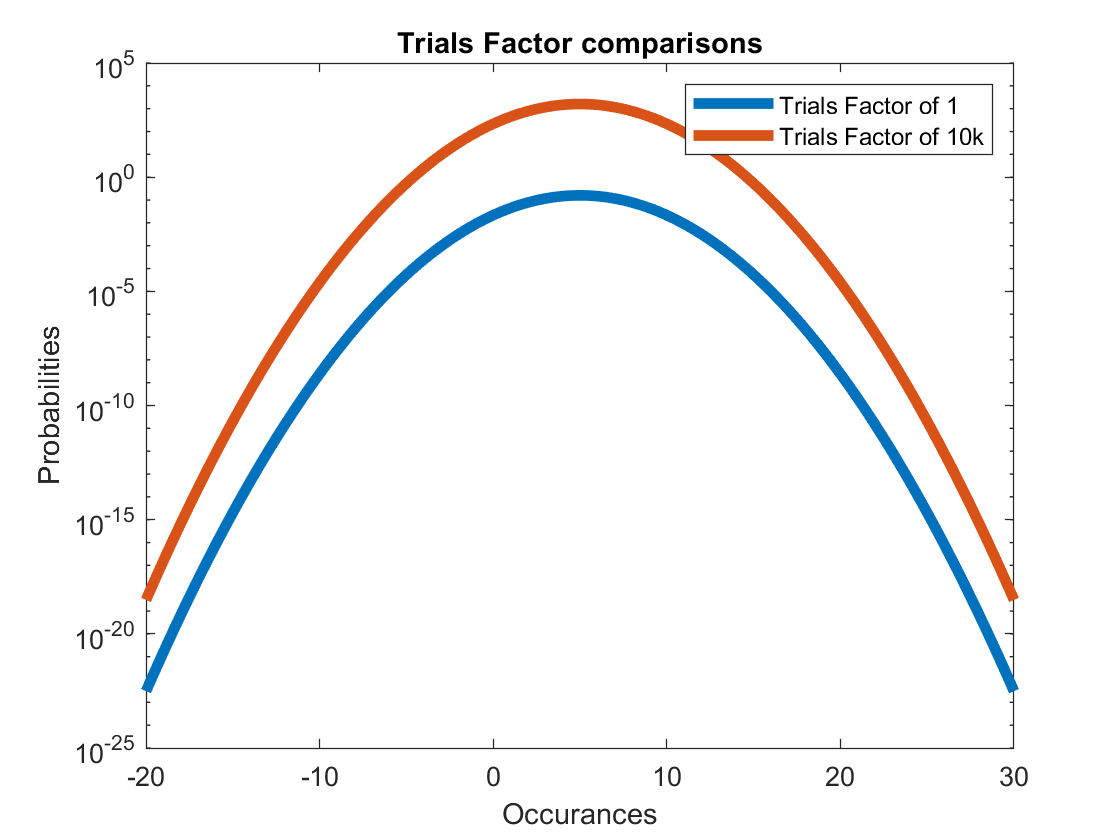

x = linspace(-20,30,1000);
semilogy(x,pdf(gaus,x), 'Linewidth',4)
hold on
semilogy(x,10000*pdf(gaus,x), 'Linewidth',4)
hold off
title('Trials Factor comparisons')
xlabel('Occurances')
ylabel('Probabilities')
legend('Trials Factor of 1', 'Trials Factor of 10k')

Looking at the probability distributions we can see that 5$\sigma$ puts the area we are intrested in way out into the flat part of the normal distributions using a linear y-scale. Meaning that a large change in the x-values of occurances results in only a small change in the probability 


prob5sig = 1/3.5e6;
det = icdf(gaus, 1-prob5sig)

det =   17.501578587325952


det_100k = icdf(gaus, 1-(prob5sig/100000))

det_100k =   22.216490152313114


Probx = (1-cdf(gaus, det,0,1))

Probx =      2.857142856749206e-07


Probx_100k = (1-cdf(gaus, det_10k,0,1))*100000

Probx_100k =      2.857147851642594e-06


brghtness_factor = det_10k/det

brghtness_factor =    1.221465016910525


Significantly changing the trails factor from 10k to 100k results in a minor change in the probabilities but the detection threshold has increased from 21.3776 for 10k t 22.2165 for 100k

function [ave] = myAverage(vec1, vec2)
ave = conv(vec1,vec2);
end